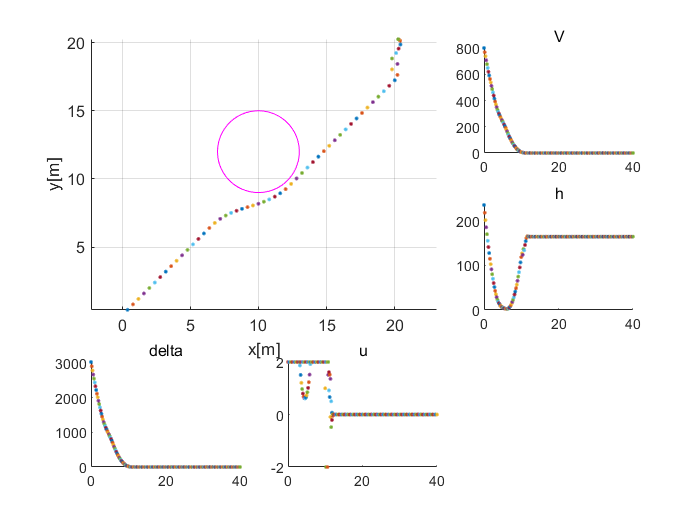

clc,clear

T=40;   %仿真时间[s]
dt=0.2;  %仿真步长

%参数
lambda=1;     %clf比例系数
gamma=4;        %cbf比例系数

x=[0;0];   %初始值
u_ref=[1,1];        %期望输入
H=diag([1 1 4]);
%坐标图

subplot(3,3,[1 2 4 5])
B=[10;12];Br=3;
rectangle('Position',[B(1)-Br,B(2)-Br,2*Br,2*Br],'Curvature',[1,1],'EdgeColor','m'); %禁行区
xlabel('x[m]')
ylabel('y[m]')
grid on,hold on,axis equal

subplot(3,3,3),title('V')
subplot(3,3,6),title('h')
subplot(3,3,7),title('delta')
subplot(3,3,8),title('u')

for t=0:dt:40
    [h,Lh]=cal_cbf(x);
    [V,LV]=cal_clf(x);
    [f,g]=cal_system(x);
    [u,delta]=QP_solve(LV,Lh,V,h,lambda,gamma,f,g,u_ref,[-2 2;-2 2],H);      
    x=(f+g*u).*dt+x;
    
    
    
    %画图
    subplot(3,3,[1 2 4 5]),hold on
    plot(x(1),x(2),'.'),hold off
    
    subplot(3,3,3),hold on
    plot(t,V,'.'),hold off
    
    subplot(3,3,6),hold on
    plot(t,h,'.'),hold off
    subplot(3,3,7),hold on
    plot(t,delta,'.'),hold off
    subplot(3,3,8),hold on
    plot(t,u,'.'),hold off
end